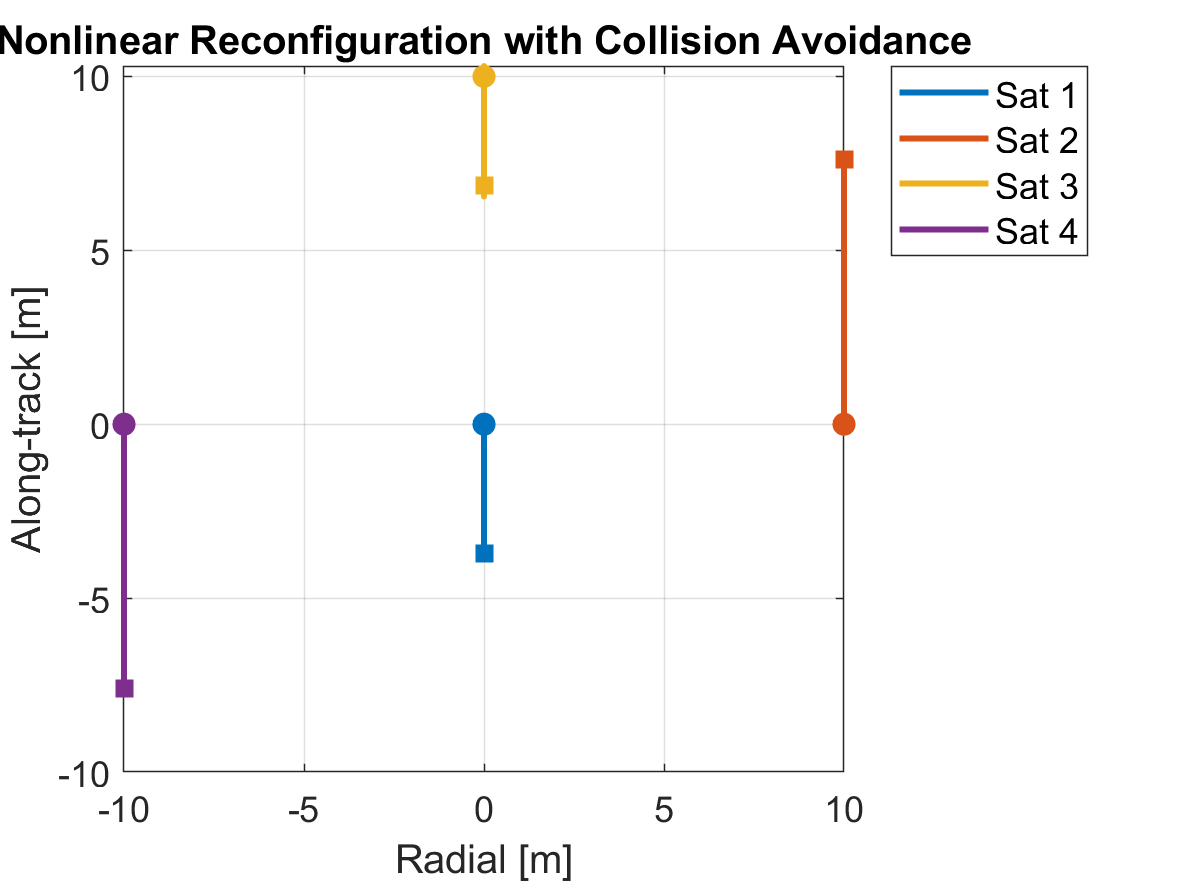

%% ========================================================================
%  SIM 07: Nonlinear Reconfiguration with Collision Avoidance (Keplerian)
%  ------------------------------------------------------------------------
%  - Demonstrates a nonlinear multi-satellite reconfiguration using
%    numerical propagation and a simplified collision avoidance approach.
%  - Satellites transition away from linear CW dynamics to full nonlinear.
%
%  Author: Sabrina Nicacio
% ========================================================================

clear; clc;

%% Constants and Setup
mu = 3.986e14;     % Earth's gravitational parameter [m^3/s^2]
Re = 6371e3;       % Earth's radius [m]
alt = 550e3;       % Orbit altitude [m]
r0 = Re + alt;     % Initial orbit radius [m]
T = 2*pi*sqrt(r0^3/mu); % Orbital period [s]

N = 4;             % Number of satellites
tf = 0.25 * T;     % Maneuver duration [s]
dt = 10;           % Time step [s]
steps = floor(tf/dt);
r_min = 10;        % Minimum separation [m]

% Initial positions in LVLH frame
x0 = [...
     0     0     0;
    10     0     0;
     0    10     0;
   -10     0     0];

% Desired final positions (new formation)
xf = [...
     0    10     0;
    10    10     0;
     0   -10     0;
   -10   -10     0];

%% Dynamics Propagation
X = zeros(steps, 3, N);  % State history
U = zeros(steps, 3, N);  % Thrust history

mass = 10;               % Satellite mass [kg]
umax = 0.05;             % Max thrust acceleration [m/s^2]

% Initialize positions
for i = 1:N
    X(1,:,i) = x0(i,:);
end

% Propagation loop
for k = 1:steps-1
    for i = 1:N
        pos = squeeze(X(k,:,i));
        error = xf(i,:) - pos;
        u = 0.001 * error;

        % Repulsion for collision avoidance
        for j = 1:N
            if j ~= i
                d = pos - squeeze(X(k,:,j));
                dist = norm(d);
                if dist < r_min && dist > 0
                    u = u + (r_min - dist) * (d / dist);
                end
            end
        end

        % Saturate thrust
        if norm(u) > umax
            u = u / norm(u) * umax;
        end

        % Store and update state
        U(k,:,i) = u;
        X(k+1,:,i) = pos + dt * u; % Euler integration
    end
end

%% Compute Delta-V
deltaV = zeros(N,1);
for i = 1:N
    acc = squeeze(U(:,:,i));
    deltaV(i) = sum(vecnorm(acc, 2, 2) * dt);
end

%% Plot Results
figure;
hold on; grid on; box on;
colors = lines(N);

% Plot each satellite’s trajectory with distinct markers
for i = 1:N
    plot(X(:,1,i), X(:,2,i), '-', 'Color', colors(i,:), 'LineWidth', 2);                  % Trajectory
    scatter(X(1,1,i), X(1,2,i), 60, colors(i,:), 'filled', 'Marker', 'o');               % Start
    scatter(X(end,1,i), X(end,2,i), 60, colors(i,:), 'filled', 'Marker', 's');           % End
end

xlabel('Radial [m]', 'FontSize', 18);
ylabel('Along-track [m]', 'FontSize', 18);
title('Nonlinear Reconfiguration with Collision Avoidance', 'FontSize', 20);

% Create custom legend using dummy plots for clarity
h = zeros(N, 1);
for i = 1:N
    h(i) = plot(NaN, NaN, '-', 'Color', colors(i,:), 'LineWidth', 2);
end
legend(h, {'Sat 1', 'Sat 2', 'Sat 3', 'Sat 4'}, 'FontSize', 12, 'Location', 'northeastoutside');
set(gca, 'FontSize', 12);

exportgraphics(gcf, 'SIM07.png', 'Resolution', 300);


%% Display and Save Delta-V
disp('Total Delta-V per Satellite [m/s]:');

Total Delta-V per Satellite [m/s]:


disp(deltaV);

   29.0248
    7.6001
   34.6429
    7.6001




writematrix(deltaV, 'SIM07_deltaV_table.csv');